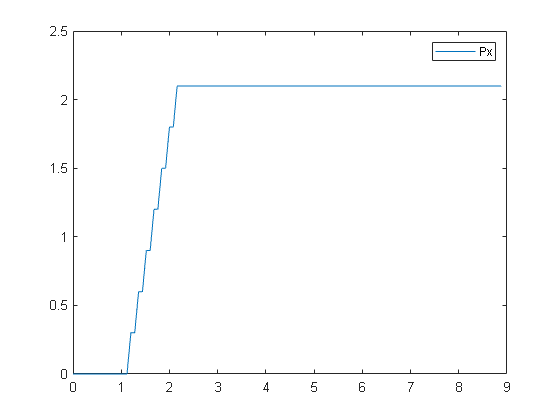

dt = 0.8e-1;  
time_end = 9;
steps0=[];
steps = floor(time_end / dt);
time = 0;
zmprefx=[];
zmprefy=[];
[pxref, pyref] = create_step_pattern(0.3, 0.1, 7, 0.1, dt, time_end);
tplot = [];
for step = 1:steps
    tplot = [tplot time];
    zmprefx = [zmprefx,  pxref(step)];
    zmprefy = [zmprefy,  pyref(step)];
    time = time + dt;
end


plot(tplot, zmprefx);
legend('Px');

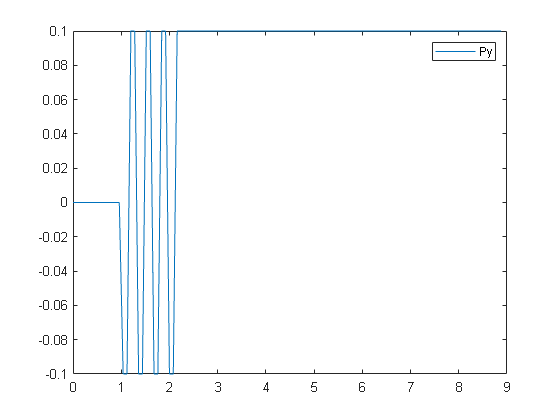

plot(tplot, zmprefy);
legend('Py');

### **fucntion de create_step_pattern**

function [pxref, pyref] = create_step_pattern(dX, dY, N, Tstep, Ts, Tend)
    % Inputs:
    %     dX (float): Step length in X direction
    %     dY (float): Step distance in sideways direction (Y)
    %     N (int): Amount of steps to take
    %     Tstep (float): Duration of the step in seconds
    %     Ts (float): Sampling time in seconds
    %     Tend (float): Simulation end time in seconds
    % 
    % Outputs:
    %     Tuple of
    %         prefx: Array of step positions in X direction
    %         prefy: Array of step positions in Y direction
    pxref = [];
    pyref = [];
    xr = 0;  %current positions in the X directions.
    yr = 0;  %current positions in the Y directions.

    total_samples = floor(Tend / Ts);
    samples_per_step = floor(Tstep / Ts);
    nlatest = floor(1 / Ts-samples_per_step);       % Idle one step period
    nlast = floor(Tend / Ts);   % Last step to do
    step_count = 0;
    for i = 0:total_samples-1
        if i > (nlatest + samples_per_step) & (step_count <= N)
            if i > nlast
                yr = 0;
            elseif yr == 0
                yr = -dY;
            else
                yr = -yr;
                xr = xr + dX;
            end

            nlatest = i;
            step_count =step_count+ 1;
        end

        pxref = [pxref xr];
        pyref = [pyref yr];
    end
end